# Stability and forced response of a nonlinear Mathieu equation

We consider the following mathieu equation with time varying stiffness coefficients.


$$m \ddot{x} + c \dot{x} + \omega_0^2 ( 1 + \cos(\Omega t)) x + \gamma  ( 1 +  \lambda \cos(\Omega t)) x^3  = 0  $$


clear all, clc

## Build Model

%% Parameters
c = 0.1;  % Damping
w0 = 1; % Natural Frequency
lam3 = -0.1;
gam3 = -0.1;
eps  = 0.2;
dampnl = 0;
[M,C,K,g,fnl] = build_model(w0^2,c,lam3,gam3, dampnl);

## Dynamical system setup

We consider the parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'notation','multiindex')

## Add forcing

DS.add_forcing(g,0.3);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();


 The first 2 eigenvalues are given as 
  -0.0500 + 0.9987i
  -0.0500 - 0.9987i



#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

sigma_out = 0
sigma_in = 1


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order

setup options

outdof = 1;
set(S.Options,    'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7)
set(S.FRCOptions, 'outdof',outdof, 'coordinates','cartesian')
set(S.FRCOptions, 'branchSwitch',true,'periodsRatio',2) %continue BPs of primary branch, 2T response
set(S.contOptions,'PtMX',40,'h_min',1e-4,'bi_direct',false)

choose frequency range around the master mode frequency

omega0 = imag(S.E.spectrum(1));
OmegaRange =[1.6,2.6]*omega0  % Subharmonic resonance at Omega = 2 omega_0

OmegaRange =     1.5980    2.5967



epSamp = [0.2,0.21,0.22];


Extract forced response curve

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.04E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 8.38E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 9.07E-03 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.12E-02 MB

 Run='SSMsweep0.2.po': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.14e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period         amp1        Znorm
    0  00:00:01   1.1350e+01      1  EP      1.5980e+00   7.8638e+00   0.0000e+00   0.0000e+00
   10  00:00:21   7.9847e+00      2          2.4780e+00   5.0713e+00   0.0000e+00   0.0000e+00
   11  00:00:24   7.

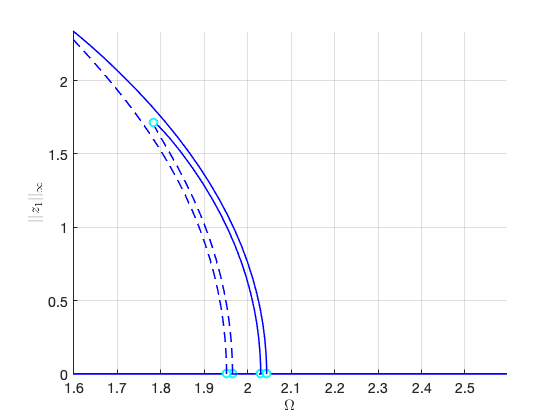

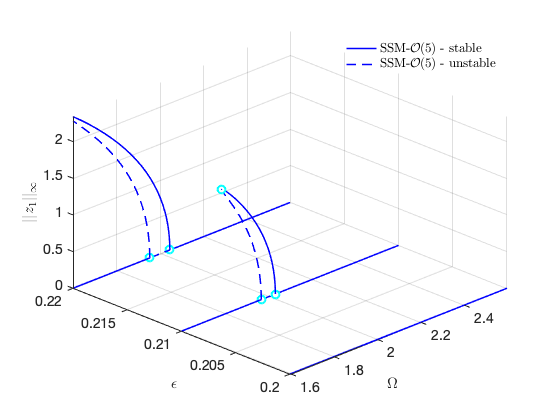

startFRCSSM = tic;

Sweep = S.SSM_poSweeps('SSMsweep',resModes,order,epSamp,OmegaRange);

timings.FRCSSM = toc(startFRCSSM);
figFRC = gcf;

## Get results from full system

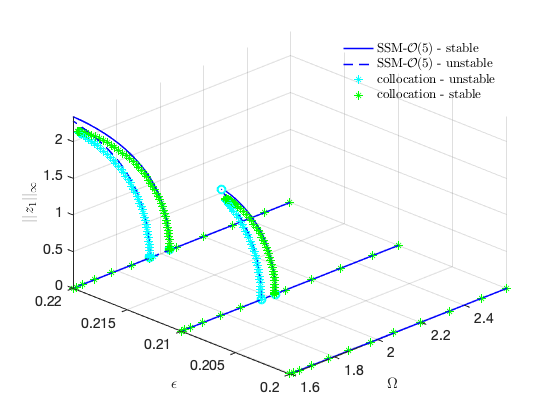


 Run='FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.14e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:01   1.1350e+01      1  EP      1.5980e+00   7.8638e+00   2.0000e-01   0.0000e+00
   10  00:00:06   7.9847e+00      2          2.4780e+00   5.0713e+00   2.0000e-01   0.0000e+00
   11  00:00:06   7.7694e+00      3  EP      2.5967e+00   4.8393e+00   2.0000e-01   0.0000e+00

 Run='FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.14e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps 

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco,'branchSwitch','true','periodsRatio',2) % include new branches, 2T periodic response
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',15,'NTST', 30,'PtMX',60,'bi_direct',false); %for convergence, smaller stepsize

figure(figFRC)
hold on
startcoco = tic;
Sweep_coco = coco.coco_poSweeps(epSamp,OmegaRange);

timings.cocoFRC = toc(startcoco);

## Stability Diagram from Reduced Dynamics

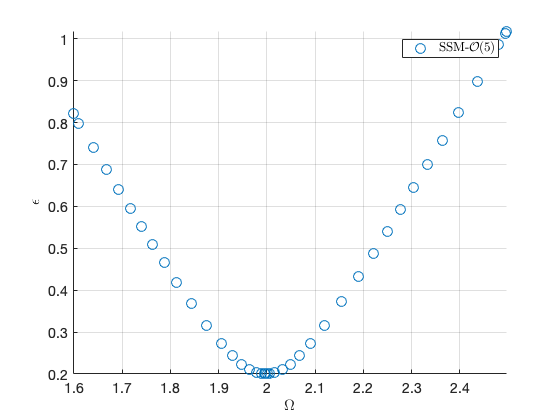

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.04E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 8.38E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 9.07E-03 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.12E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  4.88e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:00   4.8763e+00      1  EP      0.0000e+00   3.1455e+00
    2  00:00:01   4.8845e+00      2  PD      1.9975e-01   3.1455e+00
    5  00:00:02   5.0773e+00      3  EP      1.0000e+00   3.1455e+00

 Run='ROM_family_bif1': Continue bifurcations from point 2 in run 'ROM_detect_bif'.

    STEP   

Total time spent on Stability Diagram computation = 00:01:26


set(S.contOptions,'PtMX',50,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)
PlotSD = true;

p0 = [2*omega0,0]; % Initial condition
epRange = [0,1];
figure();
startSDSSM = tic;
SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);

timings.SDSSM = toc(startSDSSM);
figSD = gcf;

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

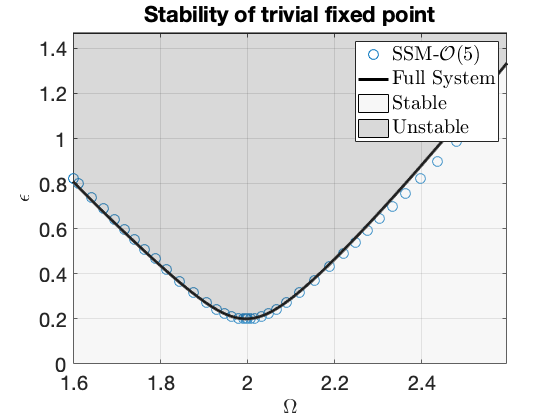


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  6.90e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:00   6.8962e+00      1  EP      0.0000e+00   1.9975e+00
    2  00:00:04   6.9020e+00      2  SN      1.9998e-01   1.9975e+00
    2  00:00:04   6.9020e+00      3  BP      1.9998e-01   1.9975e+00
    5  00:00:04   7.0397e+00      4  EP      1.0000e+00   1.9975e+00

 Run='full_family_PD_1': Continue bifurcations from point 2 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.92e-08  1.55e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period       

   10  00:00:07   1.5531e+01      2          1.9181e+00   6.5513e+00   2.5298e-01


   20  00:00:13   1.5996e+01      3          1.7206e+00   7.3035e+00   5.7577e-01


   26  00:00:16   1.6623e+01      4  EP      1.5980e+00   7.8638e+00   8.0875e-01

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:16   1.5476e+01      5  EP      1.9975e+00   6.2911e+00   1.9998e-01
   10  00:00:22   1.5344e+01      6          2.0761e+00   6.0528e+00   2.5706e-01
   20  00:00:25   1.5015e+01      7          2.3323e+00   5.3880e+00   7.3409e-01
   26  00:00:28   1.4884e+01      8  EP      2.5967e+00   4.8393e+00   1.3346e+00


nCycles = 10;

coco_sd = cocoWrapper(DS, nCycles, []);
set(coco_sd.Options, 'NAdapt', 1, 'PtMX',20, 'bi_direct',true);
set(coco_sd,'branchSwitch',true)

figure(figSD);
hold on;
startcoco = tic;
SD_full = coco_sd.extract_Stability_Diagram(OmegaRange,epRange,'amp',p0,'SN',PlotSD);

timings.cocoFRC = toc(startcoco);
